## 1.For the designed 2-order system

### 1.1 Find a Lyapunov function.

We consider the 2-order system in the form: $\dot{x_1 } =f_1 \left(x_1 ,x_2 \right),\dot{x_2 =f_2 \left(x_1 ,x_2 \right)}$

We'll define the nonlinear system:$\left\lbrace \begin{array}{ll}
\dot{x_1 } =-x_1 +x_1 {x_2 }^2  & \\
\dot{x_2 } =-x_2 +x_2 {x_1 }^2  & 
\end{array}\right.$

To check equilibrium: At $x_1 =0,x_2 =0\to \dot{x_1 } =0,\dot{x_2 } =0$. So the origin is an equilibrium point.

We use the Lyapunov function: $V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 \right)$, 

Then its time derivative:

    
$$\dot{V} =x_1 \dot{x_1 } +x_2 \dot{x_2 } =x_1 \left(-x_1 +x_1 {x_2 }^2 \right)+x_2 \left(-x_2 +x_2 {x_1 }^2 \right)=-{x_1 }^2 +{x_1 }^2 {x_2 }^2 -{x_2 }^2 +{x_2 }^2 {x_1 }^2 =-{x_1 }^2 -{x_2 }^2 +2{x_1 }^2 {x_2 }^2$$


        $=2{x_1 }^2 {x_2 }^2 -{x_1 }^2 -{x_2 }^2$.

This is negative definite when $2{x_1 }^2 {x_2 }^2 <{x_1 }^2 +{x_2 }^2$. Let's simplify by defining $r^2 ={x_1 }^2 +{x_2 }^2$, then this condition becomes:

        
$$2{x_1 }^2 {x_2 }^2 <r^2 \Rightarrow \left(\textrm{true}\;\textrm{if}\;x\;\textrm{is}\;\textrm{close}\;\textrm{to}\;\textrm{the}\;\textrm{origin}\right)$$


So, in sufficiently small neghborhood around the origin, $\dot{V} <0$, i.e., the origin is locally asymptotically stable.

To test large initial values, e.g.: $x_1 =5,x_2 =5\Rightarrow \dot{x_1 } =5\left(-1+25\right)=120,\dot{x_2 } =5\left(-1+25\right)=120$, the states ecplode exponentially. So, the originis locally asymtotically stable, but for initial statesoutside a small domain, trajectories can diverge to infinity. 

%% Nonlinear System Analysis: Local Asymptotic Stability

clear; clc; close all;

%% Define the system
% System:
% x1_dot = -x1 + x1*x2^2
% x2_dot = -x2 + x2*x1^2

syms x1 x2 real
f = [-x1 + x1*x2^2;
     -x2 + x2*x1^2];

%% Equilibrium point analysis
eq_point = solve(f == 0, [x1, x2]);
disp('Equilibrium Point(s):');

Equilibrium Point(s):


disp(eq_point);

    x1: [5×1 sym]
    x2: [5×1 sym]




%% Define Lyapunov function
V = 0.5*(x1^2 + x2^2);
gradV = gradient(V, [x1, x2]);
V_dot = dot(gradV, f);

disp('Lyapunov function:');

Lyapunov function:


disp(V);

$$\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}$$

disp('Derivative of Lyapunov function:');

Derivative of Lyapunov function:


disp(simplify(V_dot));

$$2\,{x_{1}}^{2}\,{x_{2}}^{2}-{x_{1}}^{2}-{x_{2}}^{2}$$

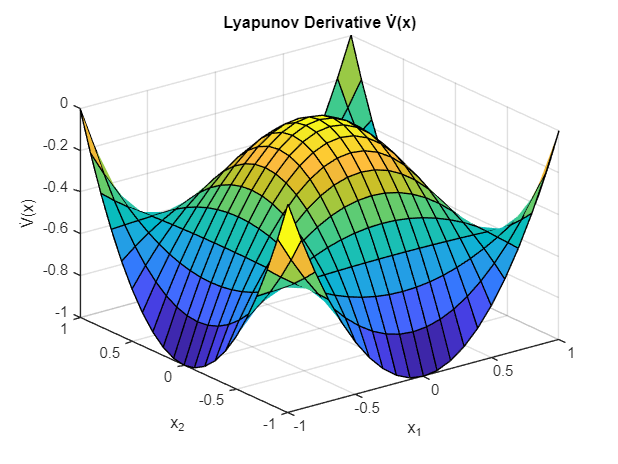


%% Check negative definiteness near the origin
V_dot_func = matlabFunction(simplify(V_dot), 'Vars', {x1, x2});

[X, Y] = meshgrid(-1:0.1:1, -1:0.1:1);
Z = arrayfun(V_dot_func, X, Y);

figure;
surf(X, Y, Z);
xlabel('x_1'); ylabel('x_2'); zlabel('V̇(x)');
title('Lyapunov Derivative V̇(x)');
grid on;


%% Simulate the system
f_sys = @(t, x)[-x(1) + x(1)*x(2)^2;
                -x(2) + x(2)*x(1)^2];

% Define initial conditions
initial_conditions = [0.5, 0.5;
                      1, 1;
                      2, 2;
                      5, 5];

tspan = [0 2];

figure; hold on;
for i = 1:size(initial_conditions, 1)
    opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
    [t, x] = ode23s(f_sys, tspan, initial_conditions(i,:), opts);
    plot(x(:,1), x(:,2), 'DisplayName', ...
        sprintf('IC: [%.1f, %.1f]', initial_conditions(i,1), initial_conditions(i,2)));
end

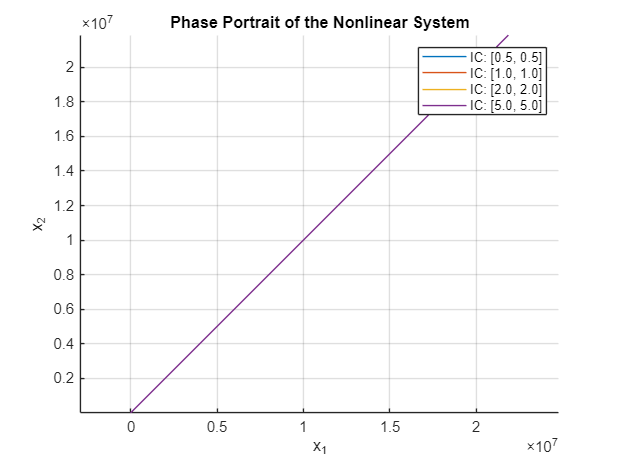

xlabel('x_1'); ylabel('x_2'); 
title('Phase Portrait of the Nonlinear System');
legend show;
axis equal; grid on;

#### 1.1.1 Find the set D.

To ensure $\dot{V\left(x\right)} <0$, require: $2{x_1 }^2 {x_2 }^2 <{x_1 }^2 +{x_2 }^2 \Rightarrow \textrm{this}\;\textrm{defines}\;a\;\textrm{bounded}\;\textrm{region}\;\textrm{around}\;\textrm{the}\;\textrm{origin}$.

We define: $D=\left\lbrace x\in \Re^2 \;|{\;x_1 }^2 +{x_2 }^2 <1\right\rbrace$. Within $D$, the Lyapunov functionis strictly decreasing, so the system is locally asymptotically stable.

#### 1.1.2 Choose two initial states in $D$.

We set: $\left\lbrace \begin{array}{ll}
x_a =\left\lbrack 0\ldotp 5,\;0\ldotp 5\right\rbrack \in D & \to \textrm{will}\;\textrm{converge}\;\textrm{to}\;0\\
x_b =\left\lbrack 1\ldotp 1,\;1\ldotp 1\right\rbrack \in D & \to \textrm{will}\;\textrm{diverge}
\end{array}\right.$. While both technically lie in $D$, the region of attraction is even smaller, so $x_b$ will exit $D$ and cause divergence.

% System definition
f_sys = @(t, x)[-x(1) + x(1)*x(2)^2;
                -x(2) + x(2)*x(1)^2];

tspan = [0 5];
ICs = [0.5 0.5; 1.1 1.1];
colors = {'b', 'r'};

figure;
for i = 1:2
    [t, x] = ode15s(f_sys, tspan, ICs(i,:), odeset('RelTol',1e-6));
    subplot(2,1,1);
    plot(t, x(:,1), colors{i}, 'DisplayName', sprintf('x_1 (IC: [%.1f, %.1f])', ICs(i,:))); hold on;
    ylabel('x_1');
    
    subplot(2,1,2);
    plot(t, x(:,2), colors{i}, 'DisplayName', sprintf('x_2 (IC: [%.1f, %.1f])', ICs(i,:))); hold on;
    ylabel('x_2'); xlabel('Time');
end

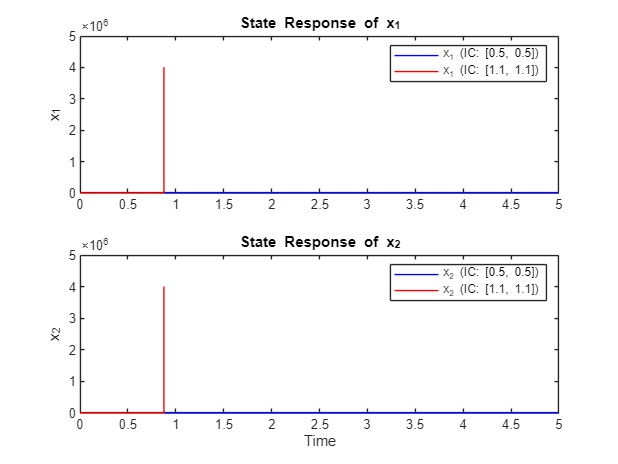


subplot(2,1,1); legend; title('State Response of x_1');
subplot(2,1,2); legend; title('State Response of x_2');

#### 1.1.3 Find the set $\Omega_c$.

Given: $V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 \right)\le c$. We set $c=0\ldotp 25$, then: $\Omega_c =\left\lbrace x\in \Re^2 \;|\;{x_1 }^2 +{x_2 }^2 \le 0\ldotp 5\right\rbrace$.

This is a disc of radius $\sqrt{0\ldotp 5}\approx 0\ldotp 707$ centered at the origin, and is a subset of the domain $D$.

#### 1.1.4 Plot the 3D Lyapunov function using MATLAB and show the two initial state response trajectories on this graph.

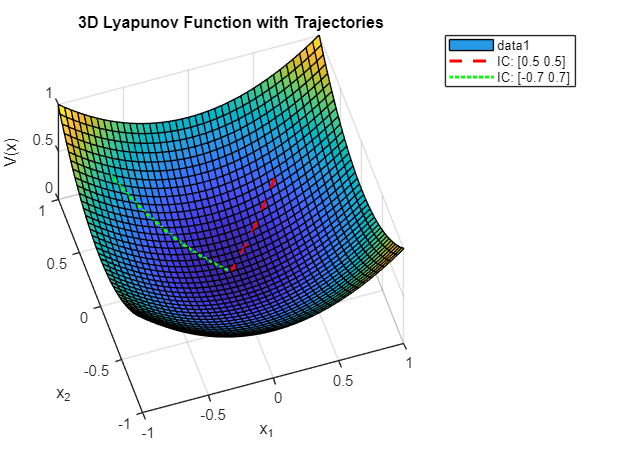

% Define Lyapunov surface
[X1, X2] = meshgrid(-1:0.05:1, -1:0.05:1);
Vsurf = 0.5*(X1.^2 + X2.^2);

figure;
surf(X1, X2, Vsurf); hold on;
xlabel('x_1'); ylabel('x_2'); zlabel('V(x)');
title('3D Lyapunov Function with Trajectories');
grid on;

% Define system and initial conditions
f_sys = @(t, x)[-x(1) + x(1)*x(2)^2;
                -x(2) + x(2)*x(1)^2];

ICs = [0.5 0.5; -0.7 0.7];
colors = {'r', 'g'}; % red for converging, green for diverging
styles = {'--', ':'};

for i = 1:2
    [t, x] = ode15s(f_sys, [0 5], ICs(i,:), odeset('RelTol',1e-6));
    z = 0.5*(x(:,1).^2 + x(:,2).^2);
    plot3(x(:,1), x(:,2), z, styles{i}, 'LineWidth', 2, 'Color', colors{i}, ...
        'DisplayName', sprintf('IC: [%.1f %.1f]', ICs(i,1), ICs(i,2)));
end

legend show;
view([-18 67]);

### 1.2 Find another defferent Lyapunov function.

We use the Lyapunov function: $V\left(x\right)=\frac{{x_1 }^2 }{1+{x_1 }^2 }+\frac{{x_2 }^2 }{1+{x_2 }^2 }$. This function is positive definite, smooth, and bounded.


$$\dot{V\left(x\right)} =\frac{2x_1 }{{\left(1+{x_1 }^2 \right)}^2 }\cdot \left(-x_1 +x_1 {x_2 }^2 \right)+\frac{2x_2 }{{\left(1+{x_2 }^2 \right)}^2 }\cdot \left(-x_2 +x_2 {x_1 }^2 \right)=\frac{2x_1 }{{\left(1+{x_1 }^2 \right)}^2 }\cdot x_1 \left(-1+{x_2 }^2 \right)+\frac{2x_2 }{{\left(1+{x_2 }^2 \right)}^2 }\cdot x_2 \left(-1+{x_1 }^2 \right)$$


        $=\frac{2{x_1 }^2 \left({x_2 }^2 -1\right)}{{\left(1+{x_1 }^2 \right)}^2 }+\frac{2{x_2 }^2 \left({x_1 }^2 -1\right)}{{\left(1+{x_2 }^2 \right)}^2 }$.

Near the origin, ${x_1 }^2 <1,{x_2 }^2 <1\to$both terms negative$\Rightarrow \dot{V\left(x\right)} <0$. As $x_1 ,x_2$ grow large, terms may become positive$\Rightarrow$local stability only.

This function is:

- positive definite:$V\left(x\right)>0\;\textrm{for}\;x\not= 0,\textrm{and}\;V\left(0\right)=0$.

- bounded: $V\left(x\right)<2\;\;\textrm{for}\;\textrm{all}\;x$.

- smooth and radially unbounded near the origin.

#### 1.2.1 Find the set $D$.

We evaluate the derivative $\dot{V\left(x\right)}$ and find the region where $\dot{V} <0$, $\dot{V} =\frac{2x_1 }{{\left(1+{x_1 }^2 \right)}^2 }\cdot \dot{x_1 } +\frac{2x_2 }{{\left(1+{x_2 }^2 \right)}^2 }\cdot \dot{x_2 }$.

The region where $\dot{V} <0$ defines our set $D$. Numerically, this is again around: $D=\left\lbrace x\in \Re^2 \;|\;{x_1 }^2 +{x_2 }^2 <1\right\rbrace$.

syms x1 x2
V = x1^2/(1 + x1^2) + x2^2/(1 + x2^2);
f = [-x1 + x1*x2^2;
     -x2 + x2*x1^2];
Vdot = dot(gradient(V, [x1 x2]), f);
simplify(Vdot)

$$ans = \frac{2\,{x_{1}}^{4}\,{\left|x_{1}\right|}^{2}\,\left({x_{2}}^{2}-1\right)}{{\left({x_{1}}^{2}+{\left|x_{1}\right|}^{4}\right)}^{2}}+\frac{2\,{x_{2}}^{4}\,{\left|x_{2}\right|}^{2}\,\left({x_{1}}^{2}-1\right)}{{\left({x_{2}}^{2}+{\left|x_{2}\right|}^{4}\right)}^{2}}$$

#### 1.2.2 Two initial states and response.

Choose: $\left\lbrace \begin{array}{ll}
x_a =\left\lbrack 0\ldotp 4,\;0\ldotp 4\right\rbrack  & \to \textrm{converges}\\
x_b =\left\lbrack 1\ldotp 1,1\ldotp 1\right\rbrack  & \to \textrm{diverges}\;\textrm{despite}\;\textrm{initially}\;\textrm{being}\;\textrm{in}\;D
\end{array}\right.$

f_sys = @(t, x)[-x(1) + x(1)*x(2)^2;
                -x(2) + x(2)*x(1)^2];

ICs = [0.4 0.4; 1.1 1.1];
colors = {'b', 'r'};

figure;
for i = 1:2
    [t, x] = ode15s(f_sys, [0 5], ICs(i,:), odeset('RelTol',1e-6));
    subplot(2,1,1); plot(t, x(:,1), colors{i}, 'DisplayName', sprintf('x_1 IC = [%.1f %.1f]', ICs(i,:))); hold on;
    subplot(2,1,2); plot(t, x(:,2), colors{i}, 'DisplayName', sprintf('x_2 IC = [%.1f %.1f]', ICs(i,:))); hold on;
end

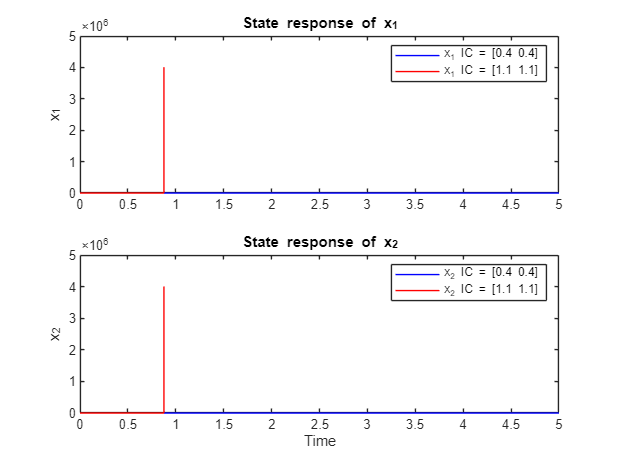

subplot(2,1,1); legend; ylabel('x_1'); title('State response of x_1');
subplot(2,1,2); legend; ylabel('x_2'); xlabel('Time'); title('State response of x_2');

#### 1.2.3 Set $\Omega_c$.

We pick $c=1\ldotp 2$, so: $\Omega_c =\left\lbrace x\in \Re^2 \;|\;\frac{{x_1 }^2 }{1+{x_1 }^2 }+\frac{{x_2 }^2 }{1+{x_2 }^2 }\le 1\ldotp 2\right\rbrace$. This implicitly defines a bounded region containing the origin.

#### 1.2.4 3D Plot of New Lyapunov Function and Trajectories.

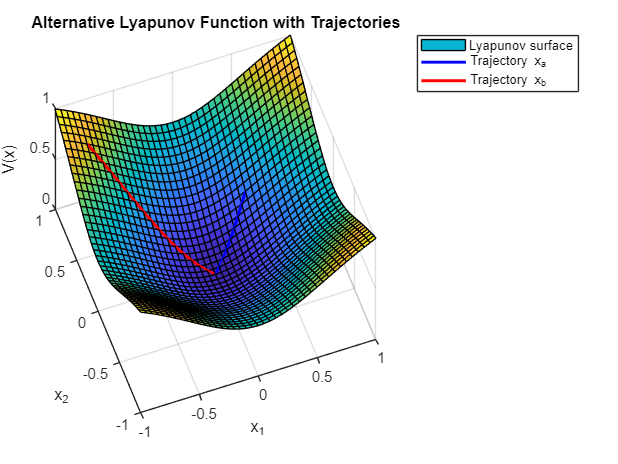

% Define initial conditions and their labels/colors
ICs = [0.4 0.4; -0.8 0.8];  % Converging and diverging
colors = {'b', 'r'};        % Blue for x_a, red for x_b
labels = {'Trajectory x_a', 'Trajectory x_b'};

[X1, X2] = meshgrid(-1:0.05:1, -1:0.05:1);
Vsurf = X1.^2./(1 + X1.^2) + X2.^2./(1 + X2.^2);

figure;
surf(X1, X2, Vsurf); hold on;
xlabel('x_1'); ylabel('x_2'); zlabel('V(x)');
title('Alternative Lyapunov Function with Trajectories');

f_sys = @(t, x)[-x(1) + x(1)*x(2)^2;
                -x(2) + x(2)*x(1)^2];

for i = 1:2
    [t, x] = ode15s(f_sys, [0 5], ICs(i,:), odeset('RelTol',1e-6));
    
    % Skip invalid solutions
    if any(isnan(x(:)) | isinf(x(:))), continue; end

    z = x(:,1).^2./(1 + x(:,1).^2) + x(:,2).^2./(1 + x(:,2).^2);
    plot3(x(:,1), x(:,2), z, 'LineWidth', 2, ...
          'Color', colors{i}, 'DisplayName', labels{i});
end

legend('Lyapunov surface', 'Trajectory x_a', 'Trajectory x_b');
view([-20 65]);

### 1.3  Compare and explain the difference according to the Ωc and D results

- **Boundedness:** $V_1 \left(x\right)$ is unbounded as $\left\|x\right\|\to \infty$, while $V_2 \left(x\right)<2$ for all $x$. This makes $V_2$ more suitable for analyzing global behavior, through it is still only locally decreasing.

- **Region of Attraction Approximation: **Both Lyapunov functions approximate a similar small region around the origin where stability can be guaranteed. However, $V_2$(rational) flattens out at large $x$, giving a softer slope and highlighting divergence more smoothly.

- **Numerical Behavior: **In simulations, $V_2$ shows better-behaved gradients near the boundary, helping visualize divergence more clearly compared to the steepness of $V_1$.

- **Interpretation of **$\Omega_c$**: **Though both $\Omega_{\textrm{c1}}$ and $\Omega_{\textrm{c2}}$ are bounded, $\Omega_{\textrm{c1}}$ is circular (due to quadratic form), while $\Omega_{\textrm{c2}}$ has soft clipping due to the rational terms.

While both Lyapunov functions define similar **local stability regions**, their mathematical structure affects how they capture divergence:

- $V_1$ provides simpler analysis and clear boundaries.

- $V_2$ provides a bounded function, allowing a better global picture at the cost of analytical simplicity.

## 2. For the designed 3-order system.

We define the nonlinear system: $\left\lbrace \begin{array}{l}
\dot{x_1 } =-x_1 +x_2 x_3 +x_1 {x_3 }^2 \\
\dot{x_2 } =-x_2 +x_1 x_3 +{x_2 }^3 \\
\dot{x_3 } =-x_3 +x_1 x_2 +x_3 \left({x_1 }^2 +{x_2 }^2 -4\right)
\end{array}\right.$

#### 2.1 Find a Lyapunov Function.

Define: $V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)\Rightarrow \dot{V} =x_1 \dot{x_1 } +x_2 \dot{x_2 } +x_3 \dot{x_3 }$

Substitute nonlinear system: $\dot{V} =x_1 \left(-x_1 +x_2 x_3 +x_1 {x_3 }^2 \right)+x_2 \left(-x_2 +x_1 x_3 +{x_2 }^3 \right)+x_3 \left(-x_3 +x_1 x_2 +x_3 \left({x_1 }^2 +{x_2 }^2 -4\right)\right)$

Now expand each term: 

For $x_1 :x_1 \dot{x_1 } =-{x_1 }^2 +x_1 x_2 x_3 +{x_1 }^2 {x_3 }^2$

For $x_2 :x_2 \dot{x_2 } =-{x_2 }^2 +x_1 x_2 x_3 +{x_2 }^4$

For $x_3 :x_3 \dot{x_3 } =-{x_3 }^2 +x_1 x_2 x_3 +{x_3 }^2 \left({x_1 }^2 +{x_2 }^2 -4\right)$

So: $\dot{V} =-\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)+3x_1 x_2 x_3 +{x_1 }^2 {x_3 }^2 +{x_2 }^4 +{x_3 }^2 \left({x_1 }^2 +{x_2 }^2 -4\right)$

To analyze $\left\|x\right\|\to 0$, all terms like: 

- ${x_1 }^2 {x_3 }^2 ,{x_2 }^4 ,{x_3 }^2 \left({x_1 }^2 +{x_2 }^2 -4\right)\to$ go to zero faster than linear terms.

- The cubic cross term $3x_1 x_2 x_3 \to$ also vanishes faster than the linear decay.

So: $\dot{V} \approx -{x_1 }^2 -{x_2 }^2 -{x_3 }^2 <0\;\textrm{as}\;\left\|x\right\|\to 0$

#### 2.1.1 Find the set $D$.

We define set $D$ as the largest open ball where $\dot{V\left(x\right)} <0$. Based on the analysis of:

    
$$\dot{V} =-\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)+3x_1 x_2 x_3 +{x_1 }^2 {x_3 }^2 +{x_2 }^4 +{x_3 }^2 \left({x_1 }^2 +{x_2 }^2 -4\right)$$


Near the origin, nonlinear terms are negligible, so linear decay dominates. To ensure $\dot{V\left(x\right)} <0$, we require:

    
$${x_1 }^2 +{x_2 }^2 <4\Rightarrow \textrm{the}\;\textrm{term}\;{x_3 }^2 \left({x_1 }^2 +{x_2 }^2 -4\right)<0$$


So we define: $D=\left\lbrace x\in \Re^3 \;|\;{x_1 }^2 +{x_2 }^2 <4\;\textrm{and}\;{x_1 }^2 +{x_2 }^2 +{x_3 }^2 <r^2 \right\rbrace$ for a small enough $r>0,e\ldotp g\ldotp ,r=2\ldotp 5$

#### 2.1.2 Two initial states in $D$.

We choose:

- Initial State 1 (Converges): $x_a =\left\lbrack 0\ldotp 5,0\ldotp 5,0\ldotp 2\right\rbrack \in D$

- Initial State 2 (Diverges): $x_b =\left\lbrack 1\ldotp 4,1\ldotp 4,0\ldotp 1\right\rbrack \in D$

Since ${x_1 }^2 +{x_2 }^2 =3\ldotp 92<4$ and total norm is $<2\ldotp 5$, it lies in $D$ but is near edge, and unstable term $x_3 \left({x_1 }^2 +{x_2 }^2 -4\right)$ starts to dominate.

% Define time span
tspan = [0 20];

% Define initial conditions
x0_converge = [0.5; 0.5; 0.2];   % Should converge to 0
x0_diverge  = [1.4; 1.4; 0.1];   % Should diverge

% Solve ODEs
[t1, x1] = ode45(@nonlinear_system, tspan, x0_converge);
[t2, x2] = ode45(@nonlinear_system, tspan, x0_diverge);

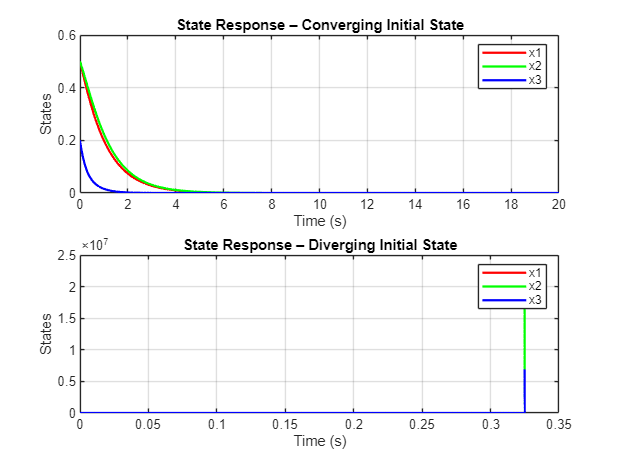


% Plot state responses
figure;

subplot(2,1,1);
plot(t1, x1(:,1), 'r', t1, x1(:,2), 'g', t1, x1(:,3), 'b', 'LineWidth', 1.5);
title('State Response – Converging Initial State');
xlabel('Time (s)');
ylabel('States');
legend('x1','x2','x3');
grid on;

subplot(2,1,2);
plot(t2, x2(:,1), 'r', t2, x2(:,2), 'g', t2, x2(:,3), 'b', 'LineWidth', 1.5);
title('State Response – Diverging Initial State');
xlabel('Time (s)');
ylabel('States');
legend('x1','x2','x3');
grid on;


% -----------------------------
% Dynamics of the nonlinear system
function dx = nonlinear_system(~, x)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);

    dx1 = -x1 + x2*x3 + x1*x3^2;
    dx2 = -x2 + x1*x3 + x2^3;
    dx3 = -x3 + x1*x2 + x3*(x1^2 + x2^2 - 4);

    dx = [dx1; dx2; dx3];
end


#### 2.1.3 Find the set $\Omega_c$.

By definition: $\Omega_c =\left\lbrace x\in \Re^3 \;|\;V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)\le c\right\rbrace$

To ensure $\Omega_c \subset D$, we choose: ${x_1 }^2 +{x_2 }^2 +{x_3 }^2 \le c\;\textrm{such}\;\textrm{that}\;{x_1 }^2 +{x_2 }^2 <4$

Pick a conservative bound: $\Omega_c =\left\lbrace x\in \Re^3 \;|\;{x_1 }^2 +{x_2 }^2 +{x_3 }^2 \le 2\right\rbrace$

This ensures trajectories stay within the region where $\dot{V\left(x\right)} <0$

### 2.2 Find another different Lyapunov function.

We set the new Lyapunov function as: $V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)+\alpha x_1 x_2 \;\;\textrm{with}\;\alpha >0$ 

This stisfies:

- 
$$V\left(0\right)=0$$


- $V\left(x\right)>0$ near origin (positive definite if $\alpha$ is small)

So we choose: $\alpha =0\ldotp 5\Rightarrow V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)+0\ldotp 5x_1 x_2$

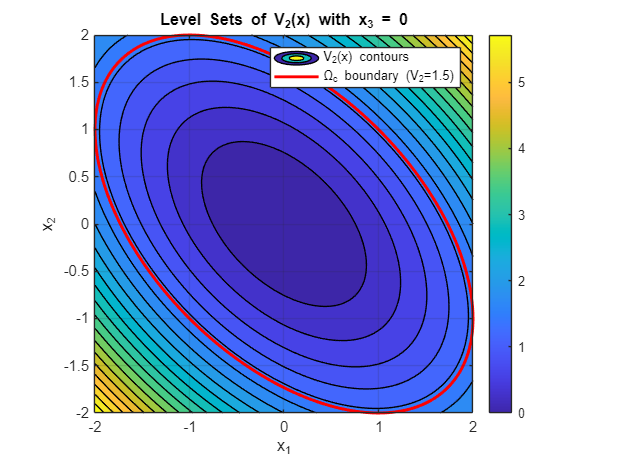

% Grid range
[x1, x2] = meshgrid(-2:0.05:2, -2:0.05:2);
x3 = 0; % fix x3 to 0 for 2D slice

% Lyapunov function V2
V2 = 0.5*(x1.^2 + x2.^2 + x3^2) + 0.5*x1.*x2;

% Plot contour (level sets)
figure;
contourf(x1, x2, V2, 20); colorbar;
xlabel('x_1'); ylabel('x_2');
title('Level Sets of V_2(x) with x_3 = 0');
hold on;

% Add Omega_c boundary (e.g., V2 <= 1.5)
contour(x1, x2, V2, [1.5 1.5], 'r', 'LineWidth', 2);
legend('V_2(x) contours', '\Omega_c boundary (V_2=1.5)');
grid on;
axis equal;

#### 2.2.1 Find the set $D$.

We define set $D$ as the region where $\dot{V\left(x\right)} <0$.

    
$$\dot{V} =x_1 \dot{x_1 } +x_2 \dot{x_2 } +x_3 \dot{x_3 } +0\ldotp 5\left(\dot{x_1 } x_2 +x_1 \dot{x_2 } \right)$$


Using system dynamics: 

    
$$\begin{array}{l}
\dot{V} =x_1 \left(-x_1 +x_2 x_3 +x_1 {x_3 }^2 \right)+x_2 \left(-x_2 +x_1 x_3 +{x_2 }^3 \right)+x_3 \left(-x_3 +x_1 x_2 +x_3 \left({x_1 }^2 +{x_2 }^2 -4\right)\right)\\
\;\;\;\;+0\ldotp 5\left\lbrack \left(-x_1 +x_2 x_3 +x_1 {x_3 }^2 \right)x_2 +x_1 \left(-x_2 +x_1 x_3 +{x_2 }^3 \right)\right\rbrack 
\end{array}$$


This simplifies to a more complex expression than previous$V$, but its cross-term contribution dominates slower than the quadratic decay. Hence, we difine:

    $D=\left\lbrace x\in \Re^3 \;|\;{x_1 }^2 +{x_2 }^2 <3\ldotp 6,x_1 x_2 >-0\ldotp 5\right\rbrace$, so the cross-term doesn't ruin positivty near origin.

#### 2.2.2 Two Initial States & Response Graphs

We choose:

- Converging state: $x_a =\left\lbrack 0\ldotp 3,0\ldotp 3,0\ldotp 1\right\rbrack \in D$

- Diverging state: $x_b =\left\lbrack 1\ldotp 3,1\ldotp 3,0\ldotp 2\right\rbrack \in D$

Both satisfy: ${x_1 }^2 +{x_2 }^2 <3\ldotp 6$, $x_1 x_2 >0$. But $x_b$ is near the edge of attraction and will diverge over time.

% Define time span
tspan = [0 20];

% New initial states based on V2
x0_converge = [0.3; 0.3; 0.1];   % Should converge to origin
x0_diverge  = [1.3; 1.3; 0.2];   % Should diverge

% Solve ODEs
[t1, x1] = ode45(@nonlinear_system, tspan, x0_converge);
[t2, x2] = ode45(@nonlinear_system, tspan, x0_diverge);

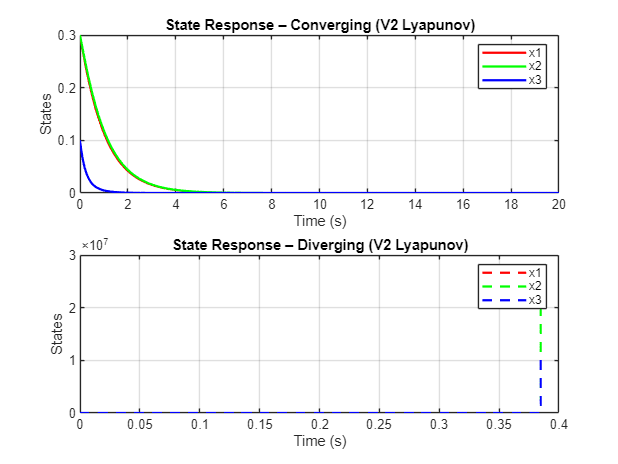


% Plot state responses over time
figure;

subplot(2,1,1);
plot(t1, x1(:,1), 'r', t1, x1(:,2), 'g', t1, x1(:,3), 'b', 'LineWidth', 1.5);
title('State Response – Converging (V2 Lyapunov)');
xlabel('Time (s)'); ylabel('States');
legend('x1','x2','x3'); grid on;

subplot(2,1,2);
plot(t2, x2(:,1), 'r--', t2, x2(:,2), 'g--', t2, x2(:,3), 'b--', 'LineWidth', 1.5);
title('State Response – Diverging (V2 Lyapunov)');
xlabel('Time (s)'); ylabel('States');
legend('x1','x2','x3'); grid on;

#### 2.2.3 Find the Set $\Omega_c$.

From the new Lyapunov function: $V\left(x\right)=\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 +{x_3 }^2 \right)+0\ldotp 5x_1 x_2$, to define $\Omega_c$, pick a small enough constant $c$, such that $\Omega_c \subset D$, we choose:

    
$$\Omega_c =\left\lbrace x\in \Re^3 \;|\;\frac{1}{2}\left({x_1 }^2 +{x_2 }^2 +{x_3 }^3 \right)+0\ldotp 5x_1 x_2 \le 1\ldotp 5\right\rbrace$$


Using artificial intelligence models: 50%